addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts'))
clear all; close all; 

In this notebook I will set up the pipeline for the network sparsification experiment. I will vary the probability of connectivity for all synaptic projections in the network. The projections will be varied either in isolation or in group. The first choice of sparsification parameters was: 1, 0.75, 0.5, 0.25, 0.1

Do I want to stick with the first choice?

The highest connection probability in the network is 7.6% and the lowest is 0.33%. This means that the highest scaling factor should not exceed 13 (100 / 7.6 = 13.16), but how do I handle the lowest scaling factor? Something like this:

I do not want to use scaling factors that will produce probabilities which will result in 0 connections. The smallest probability is 0.33% so, let's see what is the smallest scaling factor that will still produce pconn with 1 connection. First, what is that pconn?

pconn = 1 / ( N(L4E) x N(L3I) )

pconn = 1 / (188 * 28)

pconn = 1 / 5264

pconn = 0.000189 (0.019%)

Now, what is the scaling factor that decreases the pconn from 0.33% to 0.019%? 

sf_min = 0.019 / 0.33

sf_min = 0.0576

**Okay, now I have the range of scaling factor which will not result in pconn > 100% or in pconn where N(connections) < 1.**

Therefore, the scaling factor range can be between (and including) 13 and 0.06.

% set the network seed (this should be based on the exclusion criteria experiment)
netSeed = [];

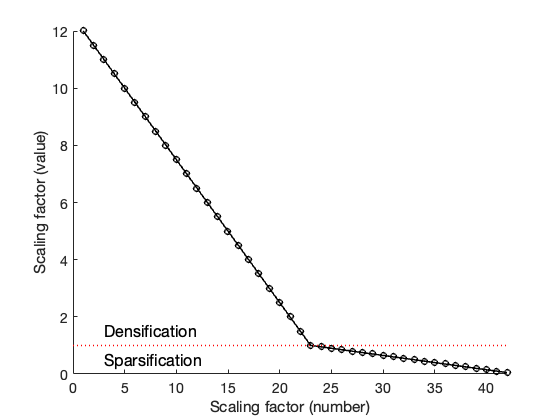

% set the scaling factor array
ScalingFactors = [12:-0.5:1.5 1:-0.05:0.01];

figure; clf; hold on;
plot(1:length([12:-0.5:1.5 1:-0.05:0.01]), [12:-0.5:1.5 1:-0.05:0.01], '-k','linewidth', 1.5)
plot(1:length([12:-0.5:1.5 1:-0.05:0.01]), [12:-0.5:1.5 1:-0.05:0.01], 'ok','linewidth', 1.5)

plot([0 length(ScalingFactors)],[1 1], ':r', 'linewidth', 1.5)
xlim([0 length(ScalingFactors)])

text(3,0.5,'Sparsification', 'fontsize',16)
text(3,1.5,'Densification', 'fontsize',16)

xlabel('Scaling factor (number)')
ylabel('Scaling factor (value)')
set(gca,'fontsize', 14)

## The experiment

varyType = 'probs';

projections = [ "all Th to L4","all L4 to L3","all L3 to L2"... % translaminar global
        "ThE to L4E","ThE to L4I","l4E to L3E","L4E to L3I","L4I to L3E","L3E to L2E","L3E to L2I","L3I to L2E","L3I to L2I"... % translaminar local
        "all (intra)layers E to E","all (intra)layers E to I","all (intra)layers I to E","all (intra)layers I to I"... % intralaminar global
        "L4E intralayer", "L4E to L4I", "L4I to L4E", "L4I intralayer", "L3E intralayer", "L3E to L3I", "L3I to L3E", "L3I intralayer", "L2E intralayer", "L2E to L2I", "L2I to L2E", "L2I intralayer"... % intralaminar local
               ];

repetitions = 50;

Ecells_percentage = 0.85;
Icells_percentage = 0.15;

synParams = struct('synstr',[1 1], 'pconn', [1 1]);

tstop = 500;

for sp = 1:length(projections)
    sparseProjection = projections(sp);
    fprintf('Sparsifying %s. (%i/%i)', sparseProjection, sp, length(projections))
    
    for sf = 1:length(ScalingFactors)
        sparseFactor = ScalingFactors(sf);
        
        sparse_info{1} = sp;  % which projection is being sparsified
        sparse_info{2} = varyType;          % which connectivity parameter is affected
        sparse_info{3} = sparseFactor;      % what scaling factor is applied
        
        parfor r = 1:repetitions
            SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', netSeed, tstop, sparse_info);
            SpikingNetwork.SparseExpInfo = sparse_info;
            
            NetSaveName = sprintf('N4_sparse%i_%s_rep%i', sp, regexprep(sparseProjection, ' ', '_'), r);
            ParallelSave(NetSaveName,SpikingNetwork)
        end
    end
end